# Complex Fourier Series

**Learning Goals**

- Relate real Fourier series to complex Fourier series.

## Real Fourier Series

Understanding complex Fourier series is easier if you have a solid understanding of real Fourier series. In this section, the essential definitions are reviewed.

### **Sine and Cosine Fourier Series**

Real Fourier series are convenient because they use standard trig functions, which are intuitively simple. For example, the definition 


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


is probably the most immedately obvious: it's a sum of sine and cosine functions. The coefficients for a signal $y(t)$ can be computed using the formulas


$$a_n = \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} y(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


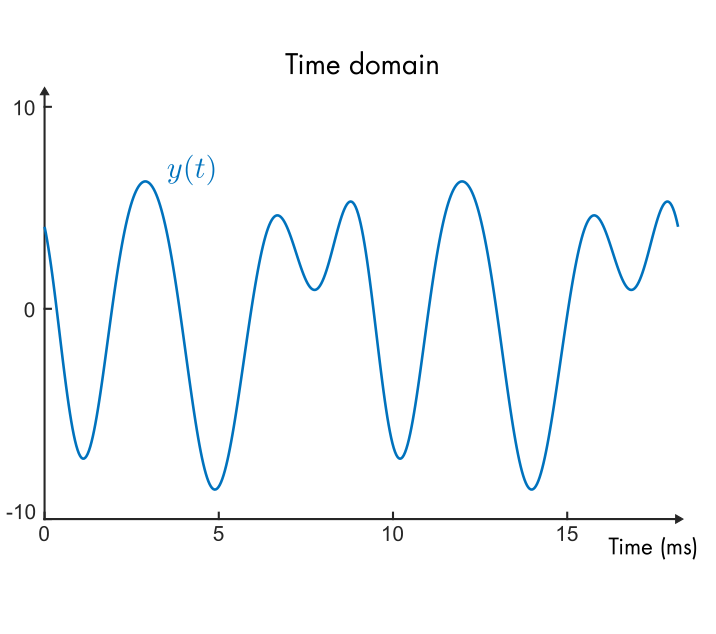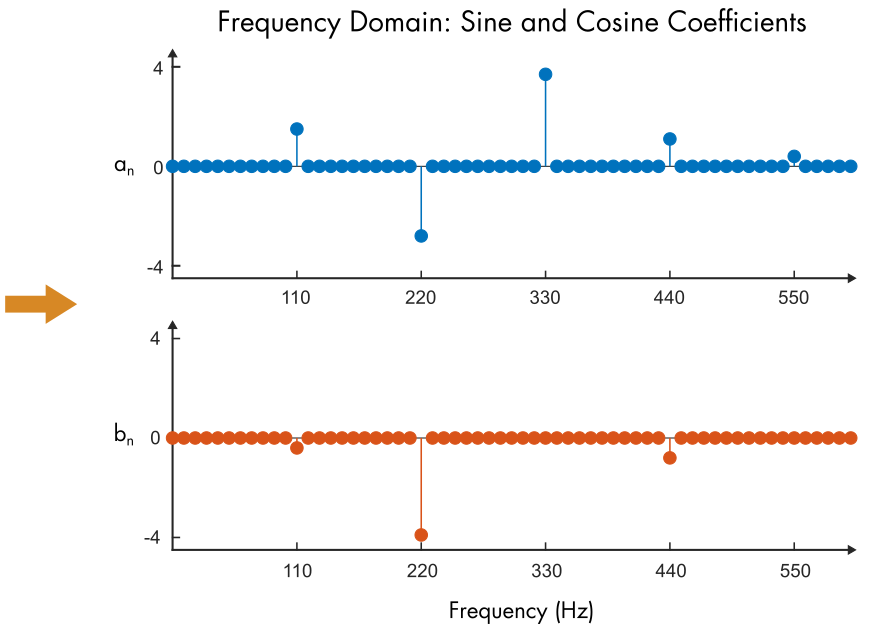

*Time and frequency domain representations of a simulated signal *$y(t)$* which approximates a guitar's A note. *

*In this example, the frequency domain is characterized by the sine and cosine coefficients *$a_n$ and $b_n$.

### **Phase and Magnitude Fourier Series**

An alternative form of the real Fourier series is


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


In this form, the constants also have more obvious meanings in terms of each mode: $A_n$ represents the magnitude of the mode and $\phi_n$ represents the phase. The two definitions can be related to each other through

$A_n = \sqrt{a_n^2 + b_n^2}$     and    $\phi_n = \text{atan2}\left( b_n,a_n\right)$

Note that phase angle is computed using the two-argument arctangent. In MATLAB, this is implented in the function [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html). It's difficult to compute the coefficients $A_n$ and $\phi_n$ in this form. Instead, coefficients are computed using the formulas for $a_n$ and $b_n$, and then converted to the magnitude and phase constants.

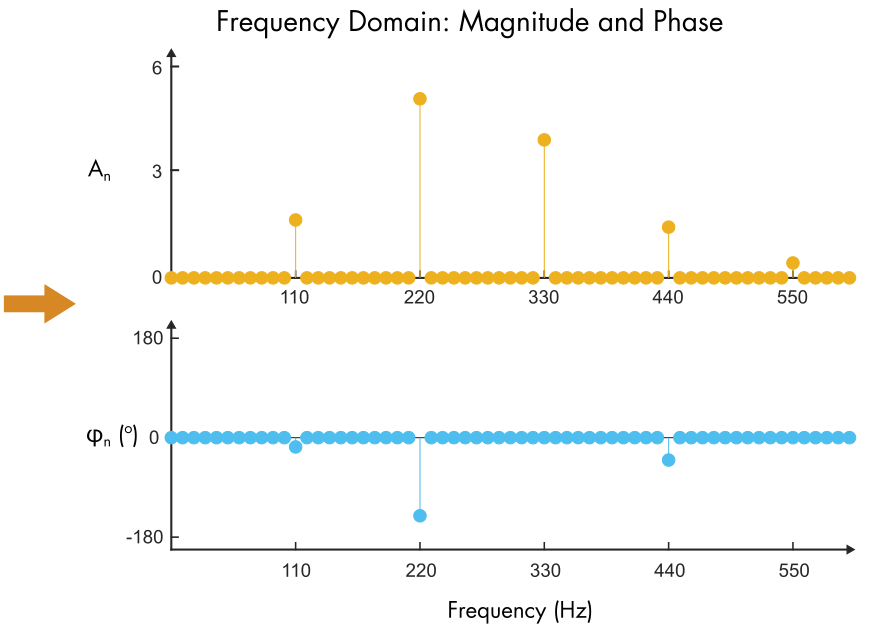

*Time and frequency domain representations of a simulated signal *$y(t)$* which approximates a guitar's A note. *

*In this example, the frequency domain is characterized by the magnitude and phase of each Fourier mode: *$A_n$ and $\phi_n$.

 **Exercise. **Compute the magnitude and phase form of the Fourier series for the signal


$$y(t) = 2 \cos(4 \pi t) + \sin( 4 \pi t) + 3 \cos( 2 \pi t)$$


assuming that $L = 0.5$ s. 

**Task 1. **What are the Fourier coefficients in the sine-cosine form? Note that $a_n, b_n = 0$ for all $n$ except $n = 1, 2$. 

% Replace the NaNs with your answers
a1 = 3;
a2 = 2;
b1 = 0;
b2 = 1;

checkEx1Task1(a1,a2,b1,b2) % This checks your answers

Correct!


**Task 2.** What are $A_n$ and $\phi_n$ (in radians)  in the magnitude and phase form of the series? You can use [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) to compute the phase in radians.

% Replace the NaNs with your answers
A1 = 3;
A2 = sqrt(5);
phi1 = atan2(b1,a1); % radians
phi2 = atan2(b2,a2); % radians

checkEx1Task2(A1,A2,phi1,phi2) % This checks your answers

Correct!


## Complex Fourier Series

By moving to the complex domain, the trigonometric functions can be rewritten in terms of exponentials. This is possible due to *Euler's identity*:


$$e^{i \theta} = \cos \theta + i \sin \theta$$


By applying this identity, the cosine and sine terms can be combined into a single series of complex exponentials. Exponentials are easy to work with because of their compact notation and simple derivative and integral formulas.

### Definition

The complex Fourier series is


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


The coefficients of the complex Fourier series can be evaluated using the integral


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


** Example. **Compute the complex Fourier series for


$$y(t) = 3 \cos( 2 \pi t)$$


assuming that $L = 0.5$ s. To compute the coefficient for $n = 1$, apply the formula, and rewrite the cosine in terms of complex exponentials.


$$\begin{array}{rl}
c_1 &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} 3 \cos( 2 \pi t) e^{ -\frac{i \pi}{0.5} t} dt
\\
&= 3 \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} + e^{- 2 \pi i t} }{2}  e^{ -2 i \pi t} dt
\\
&= \frac{3}{2} \int_{-0.5}^{0.5} 1+ e^{- 4 \pi i t} dt
\\
&= \frac{3}{2}
\\
\end{array}$$


The other coefficients will be zero except $n = -1$, since the original function has only a single frequency. Try computing the integral for $n = -1$. You should find that $c_{-1} = 3/2$.Therefore the complex Fourier series has coefficients $c_n = 0$ except $c_1 = 3/2$ and $c_{-1} = 3/2$. Run this section to see a plot of the coefficients.

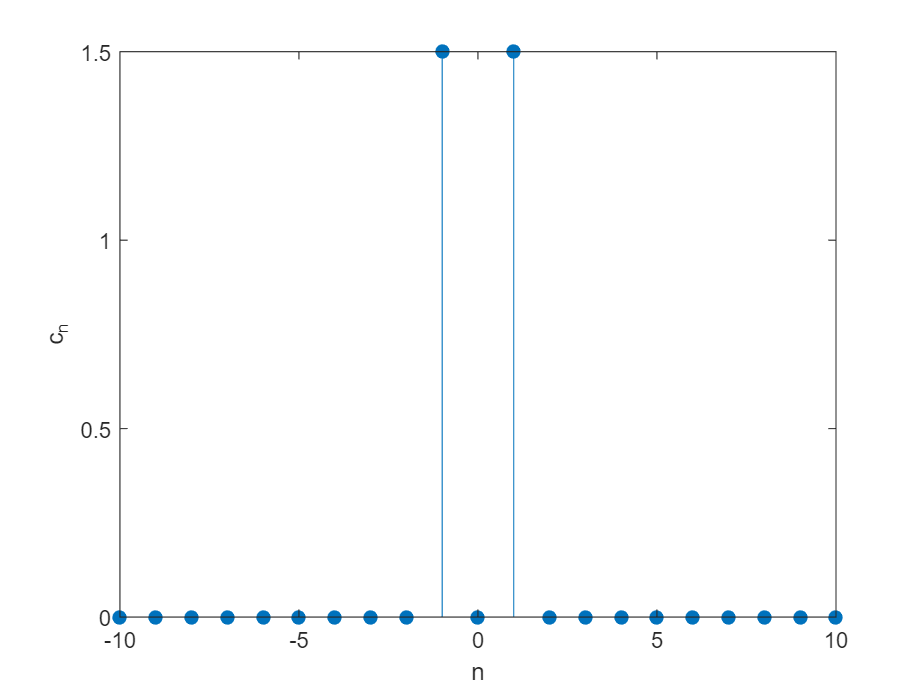

% Create the coefficient vector
freq = -10:10;
cn = zeros(size(freq));
cn([10,12]) = 3/2;
% Create the plot
stem(freq,cn,'filled')
xlabel("n")
ylabel("c_n")

At this point, it may seem that a complex function has been created from a real function. However, for this series to accurately reproduce $y(t)$ it should not have a complex part. To verify that $f(t)$ accurately reproduces $y$, you can apply Euler's formula.


$$f(t) = \frac{3}{2} e^{-2 \pi i t} +  \frac{3}{2} e^{2 \pi i t}$$


... [incomplete]....

** Example. **Compute the complex Fourier series for


$$y(t) = \sin ( 2 \pi t)$$


assuming that $L = 0.5$ s. To compute the coefficient for $n = 1$, apply the formula, and rewrite the cosine in terms of complex exponentials.


$$\begin{array}{rl}
c_1 &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} \sin( 2 \pi t) e^{ -\frac{i \pi}{0.5} t} dt
\\
&= \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} - e^{- 2 \pi i t} }{2i}  e^{ -2 i \pi t} dt
\\
&= \frac{1}{2i} \int_{-0.5}^{0.5} 1 - e^{- 4 \pi i t} dt
\\
&= \frac{1}{2i} = -2i
\\
\end{array}$$


The negative coefficient is


$$\begin{array}{rl}
c_{-1} &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} \sin( 2 \pi t) e^{ \frac{i \pi}{0.5} t} dt
\\
&= \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} - e^{- 2 \pi i t} }{2i}  e^{ 2 i \pi t} dt
\\
&= \frac{1}{2i} \int_{-0.5}^{0.5}   e^{- 4 \pi i t} - 1 dt
\\
&= \frac{1}{2i} = 2i
\\
\end{array}$$


function checkEx1Task1(a1,a2,b1,b2)
    isEqualCheck([a1,a2,b1,b2],[3,2,0,1])
end

function checkEx1Task2(A1,A2,phi1,phi2)
    isEqualCheck([A1,A2,phi1,phi2],[3,sqrt(5),0,atan2(1,2)])
end

function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end
